# Enero 2021

#### Cuestiones

#### Cuestión 1

**¿Para qué puede servir calcular la diferencia entre una imagen binarizada y la misma imagen erosionada? Razona la respuesta**

Una imagen binarizada se trata de una imagen la cual se ha pasado a 1 y 0, los colores con tonalidades gris menor a 128 pasan a valer 0, y los valores iguales o mayores a 128 pasan a valer 1

Una imagen erosionada se trata de una imagen a la cuál se le eliminan los bordes para generar una versión menos detallada de la misma imagen

El motivo de calcular la diferencia entre una imagen binarizada y la misma imagen erosionada sirve para poder formar una nueva imagen en la cuál tenemos únicamente los bordes

#### **Cuestión 2**

**¿Qué ventaja tiene utilizar el modelo de color HSI para realizar una ecualización de histograma? Compara con el modelo RGB y comenta qué consecuencias (efecto sobre la imagen) tendría aplicar la ecualización histograma en el modelo RGB**

El modelo HSI en inglés significa Hue, Saturation, Lightness, lo que es Matiz, Saturación, Luminosidad, que define un modelo de color en términos de sus componentes constituyentes. En el modelo HSI, para ecualizar el histograma podemos ecualizar solo la matriz S si queremos modificar la saturación y la matriz I si queremos modificar el brillo. En el modelo RGB, deberiamos ecualizar las 3 matrices por separado y posteriormente juntarlas, de echo sería mejor pasar la imagen al modelo YUV y ecualizar la matriz de luminancia Y en caso de que queramos ecualizar el brillo

#### **Cuestión 3**

**Una imgen monocroma (16 niveles de gris) tiene el siguiente histograma**

**h(16) = [0 0 0 1000 500 100 4000 400 1000 0 3000 0 0 0 0 0]**

**Calcular y representar el histograma ecualizado**

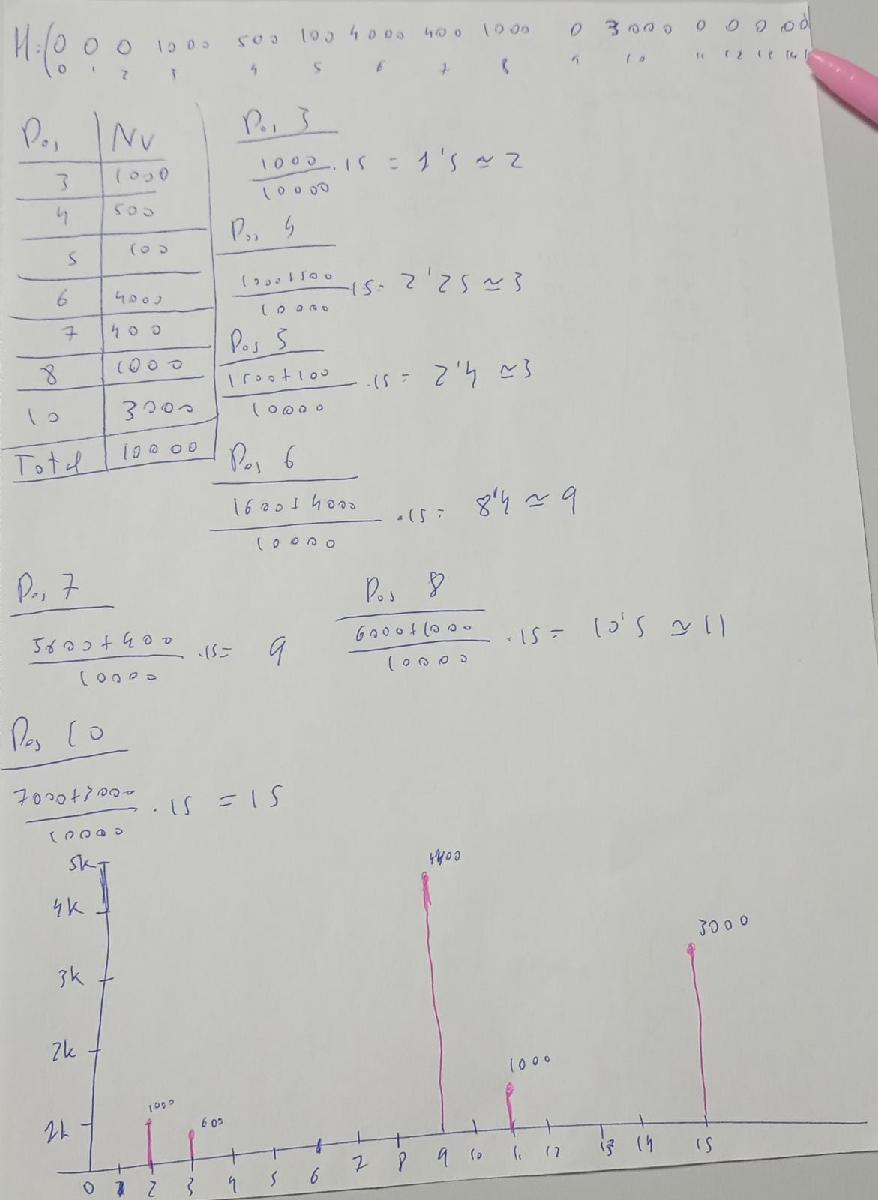

#### **Cuestión 4**

**La técnica Deep Learning está revolucionando el análisis automático de imágenes.**

**Dibujar esquema y describir lo más detallado posible el funcionamiento de una red neuronal convolucional**

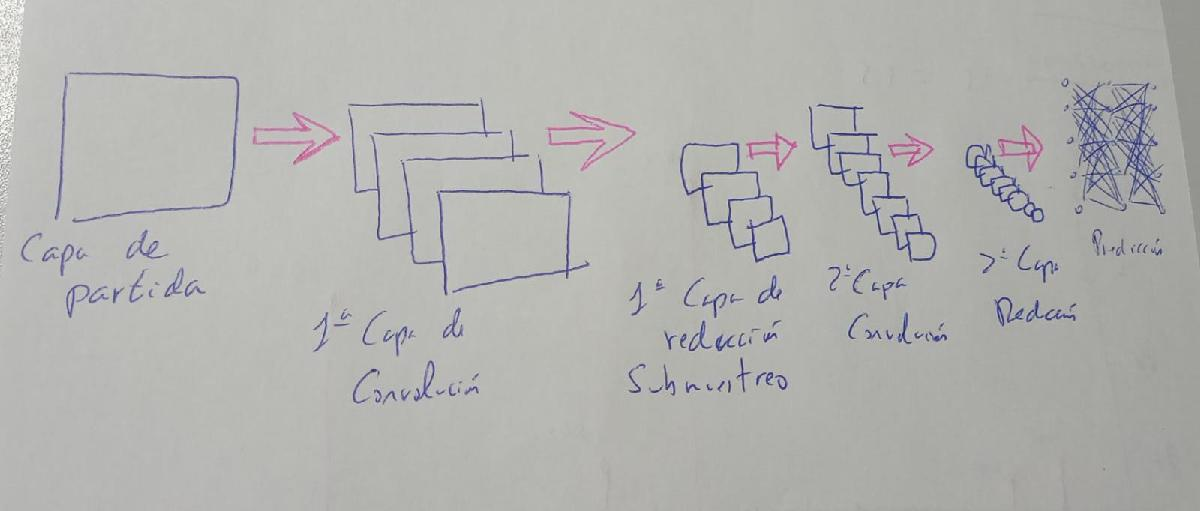

Una red neuronal convolucional funciona de la siguiente manera.

Introducimos una imagen de partida, de la cual tomamos sus píxeles como valores de entrada, todos ellos deben de estar normalizados (pix/255). A continuación de la imagen tomaremos grupos de píxeles de tamaño de la matriz Kermel, cada Kermel representará los pesos del campo receptivo local, lo cual es equivalente a un filtro adaptativo al hacer un conjunto de Kernels, submuestrearemos la imagen (pooling), esto implica reducir la cantidad de neuronas, antes de seguir convolucionando para ir reduciendo eel tamaño de las siguientes capsa (por lo que obtenemos un procesamiento más óptimo), así en cada convolución, a más convoluciones hagamos, la red podrá reconocer cada vez formas más complejas

#### **Problemas**

#### **Problema 1**

**Tenemos una imagen (13x13 px) degradada por un sistema de transmisión, en el receptor se observa mediante la transformada de Fourier el espectro de la imagen, siendo el siguiente**

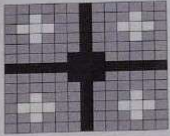

**En la imagen se observa la TF de la imagen y cómo la degradación es una interferencia de tipo sinuisoidal con varios armónicos de frecuencia desconocida, pero que se pueden identificar en las zonas de color blancos**

**a)  Si queremos eliminarlo con un filtro paso bajo, ¿Cuál sería la radio del filtro que tendremos que aplicar?**

radio = floor(sqrt(3^2 + 3^2));

**b) Programe un algoritmo en MATLAB que aplique el filtro descrito anteriormente**

Vamos a generar la imagen que nos proporcionan al inicio del enunciado

Im = [0.5 0.5 0.5 0.5 0.5 0.5 0 0.5 0.5 0.5 0.5 0.5 0.5;
    0.5 0.5 1 0.5 0.5 0.5 0 0.5 0.5 0.5 1 0.5 0.5;
    0.5 1 1 1 0.5 0.5 0 0.5 0.5 1 1 1 0.5;
    0.5 0.5 1 0.5 0.5 0.5 0 0.5 0.5 0.5 1 0.5 0.5;
    0.5 0.5 0.5 0.5 0.5 0.5 0 0.5 0.5 0.5 0.5 0.5 0.5;
    0.5 0.5 0.5 0.5 0.5 0 0 0 0.5 0.5 0.5 0.5 0.5;
    0 0 0 0 0 0 0 0 0 0 0 0 0;
    0.5 0.5 0.5 0.5 0.5 0 0 0 0.5 0.5 0.5 0.5 0.5;
    0.5 0.5 0.5 0.5 0.5 0.5 0 0.5 0.5 0.5 0.5 0.5 0.5;
    0.5 0.5 1 0.5 0.5 0.5 0 0.5 0.5 0.5 1 0.5 0.5;
    0.5 1 1 1 0.5 0.5 0 0.5 0.5 1 1 1 0.5;
    0.5 0.5 1 0.5 0.5 0.5 0 0.5 0.5 0.5 1 0.5 0.5;
    0.5 0.5 0.5 0.5 0.5 0.5 0 0.5 0.5 0.5 0.5 0.5 0.5];

Para generar el circulo que necesitaremos para el filtro paso bajo

circulo = zeros(13);

Calculamos con un doble for el tamaño del filtro paso bajo

for i = 1:13
    for j = 1:13

En todas las zonas en las que el resultado sea menor al radio, habrán 1 formando el filtro

        if sqrt((i-round(13/2))^2 +(j-round(13/2))^2) <= radio
            circulo(i,j) = 1;

        end
    end
end

H = circulo;
I_Filtrada = H.*Im;

figure
subplot(1,2,1)
imshow(Im,[])

subplot(1,2,2)
imshow(I_Filtrada, [])

**c) Programa un filtro en MATLAB que aplique un filtro Notch. La entrada del filtro será la imgen sin transformar (en el dominio del espacio) "imagenyruido.jpg"**

Obtenemos el centro

centro_u = round(13/2);
centro_v = centro_u;

Obtenemos las posiciones

Pos_X = 3;
Pos_Y = 3;
Grado = 2;

Con un bucle calcularemos el filtro Notch

for i = 1:13
    for j = 1:13

Dk y Dkn son valores propios del filtro Notch, el radio de k en positivo y negativo

        Dk = sqrt((i-centro_u-Pos_X)^2 + (j-centro_v-Pos_Y)^2);
        Dkn = sqrt((i-centro_u+Pos_X)^2 + (j-centro_v+Pos_Y)^2);

Calculamos la función de transferencia

        H(i,j) = 1/((1+(radio/Dk)^(2*Grado))*(1+(radio/Dkn)^(2*Grado)));
    end
end

Ahora realizaremos el filtro Notch sobre la imagen ya filtrada

Pos_X2 = -3;
Pos_Y2 = 3;

Con un bucle calcularemos los valores del filtro Notch

for i = 1:13
    for j = 1:13

        Dk = sqrt((i-centro_u-Pos_X2)^2 + (j-centro_v-Pos_Y2)^2);
        Dkn = sqrt((i-centro_u+Pos_X2)^2 + (j-centro_v+Pos_Y2)^2);
        H_2(i,j) = 1/((1+(radio/Dk)^(2*Grado))*(1+(radio/Dkn)^(2*Grado)));

    end
end

Filtramos

I_Filtrada = Im.*H;

Filtramos la imagen ya filtrada

I_Filtrada_2 = I_Filtrada.*H_2;

figure
subplot(1,3,1)
imshow(Im,[]);

subplot(1,3,2)
imshow(I_Filtrada, [])

subplot(1,3,3)
imshow(I_Filtrada_2)

#### **Problema 2**

**La imagen de la figura adjunta contiene rectas de 3 colores: rojo, azul y verde.**

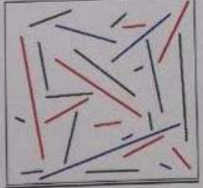

**Se desea detectar la línea más larga de la imagen cuyo color sea AZUL. La imagen se encuentra en el archivo "colores.jpg", cuyos colores no son totalmente puros. Para programar la función se dispone de la función siguiente:**

**H = Hough(imbin, Nm, Nb)**

**dónde imbin es la imagen binarizada (contiene 1 y zeros), Nm y Nb son el número de valores m y b respectivamente y H es la tabla de acumulación que devuelve la función como resultado**

**Programar una función que imprima la pendiente ma y la ordenada en el origen ba de la recta AZUL de mayor longitud a partir de la imagen de entrada colores.jpg**

**Esta sería la forma correcta de hacerlo según como se pidió en el examen.**

Empezamos quedandonos solo con la componente azul(B) de la imagen

Im = imread('Colores.PNG');

R = Im(:,:,1);
G = Im(:,:,2);
B = Im(:,:,3);

Binarizamos la componente azul

Im_Bin = imbinarize(B);

Obtenemos el tamaño de la imagenx

[N, M] = size(Im_Bin);

Nm Numeros de pedientes

Nb Numero de ordenadas en el origen

El valor 2000 es un valor, puedes poner el número que quieras,a más alto más tarda en procesar pero más preciso será

Nm = 2000;
Nb = 2000;

Llamamos a la función Hough. En el examen no se pidió programarla

H = Hough(Im_Bin, Nm, Nb);

Obtenemos la recta más larga, que tendrá el máximo valor de la salida de la función Hough

Recta_Larga = max(max(H));

Obtenemos el tamaño de la salida H, aunque en principio debería de ser igual de que Nm y Nb, pero por si acaso las inicializamos

[Nh, Mh] = size(H);

Preparamos un doble bucle para obtener los valor de la recta larga

for m = 1:Nh
    for b = 1:Mh
        if H(m,b) == Recta_Larga
            mf = m;
            mb = b;
        end
    end
end

Creamos otro bucle con el cuál dibujaremos la línea en color negro sobre fondo blanco

for y = 1:N
    for x = 1:M
        if y == round(mf*x + b)
            Im(x,y,:) = 0;
        end
    end
end

**Esta sería la forma correcta de hacerla si quieres aprender**

Empezamos quedandonos solo con la componente azul (B) de la imagen

Im = imread('Colores.PNG');

R = Im(:,:,1);
G = Im(:,:,2);
B = Im(:,:,3);

Binarizamos la componente azul

Im_Bin = imbinarize(B);

Nm Numeros de pedientes

Nb Numero de ordenadas en el origen

El valor 2000 es un valor, puedes poner el número que quieras,a más alto más tarda en procesar pero más preciso será

Nm = 2000;
Nb = 2000;

Llamamos a la función Hough

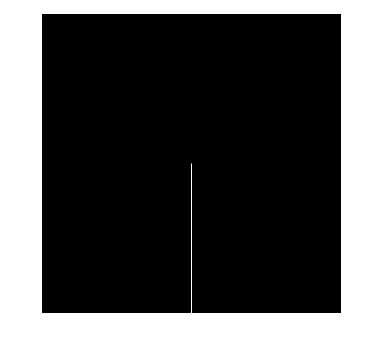

H = Hough(Im_Bin, Nm, Nb);

figure
imshow(H);

Generamos la función Hough

function H = Hough(Im_Bin, Nm, Nb)

Empezamos obteniendo el tamaño de la imagen

[N, M] = size(Im_Bin);

Calculamos el tamaño de la imagen

tam = N*M;

Vec_m, Vector de pendientes

Vec_m = linspace(-1,1,Nm);

Vec_b, Vector de ordenadas

Vec_b = linspace(-2*tam,2*tam, Nb);

Inicializamos la salida

salida = zeros(Nb, Nm);

Creamos un bucle dónde calcularemos el efecto Hough

for i = 1:N
    for j = 1:M

Acumulamos con un doble bucle cada vez que pasamos por un píxel del borde

        if Im_Bin(i,j) == 1
            for k = 1:Nb


$$b=y_1 -\left\lbrack m\right\rbrack \cdot x_1$$


                b = i - Vec_m(k)*j;

Miramos el B cuantizado más cercano al valor del b que calculamos

                dist = abs(Vec_b - b);

Buscamos el valor mínimo del vector de distancias

                ind_B = find(dist == min(dist));
                salida(k,ind_B) = salida(k,ind_B) + 1;

            end
        end
    end
end
H = salida;
end